# DSZOB, cvičenie 10.

## **Zadanie: JPEG a JPEG2000 kompresia**

**Úloha 1: JPEG kompresia**

Napíšte základný algoritmus pre JPEG kompresiu a dekompresiu - pomôžte si prednáškami.

Implementujte aj downsampling kanalov Cb a Cr. Zig-zag algoritmus už neimplementujte.

Pomôcky: rgb2ycbcr(RGB), dct2()

Umožnite jednoduchým nastavením atribútu “kvalita” ovplyvniť mieru kompresie obrázka.

• Kvalitatívne **vyhodnoťte** vplyv atribútu “kvalita” na výslednú stratu kvality obrázka. Pri akej hodnote atribútu došlo k rozpoznateľnej strate kvality ? (Vizualizujte v rámci 1 sub-plotu pre 4 rôzne hodnoty atribútu "kvalita")

• Kvantitatívne **vyhodnoťte** kompresný pomer (v %) pre rôzne hodnoty atribútu “kvalita”. (Uveďte hodnoty v tabuľke )

Ako vstupné dáta použite nasledovné obrázky (veľkosť do 400x400 pixelov pre jednoduchšie vizualizácie):

- **ľubovoľnú fotografiu**

- **syntetický obrázok (napr. nakresleny v paint-e)  **

obe v bezstratovom formate ako napr. BMP, PNG 

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

% Riesenie / Solution
QL = [16 11 10 16 24 40 51 61
12 12 14 19 26 58 60 55
14 13 16 24 40 57 69 56
14 17 22 29 51 87 80 62
18 22 37 56 68 109 103 77
24 35 55 64 81 104 113 92
49 64 78 87 103 121 120 101
72 92 95 98 112 100 103 99];

QC = [17 18 24 47 99 99 99 99
18 21 26 66 99 99 99 99
24 26 56 99 99 99 99 99
47 66 99 99 99 99 99 99
99 99 99 99 99 99 99 99
99 99 99 99 99 99 99 99
99 99 99 99 99 99 99 99
99 99 99 99 99 99 99 99];

img = imread('wolf2.png');
img2 = imread('picasso.png');
size(img)

ans =    400   400     3


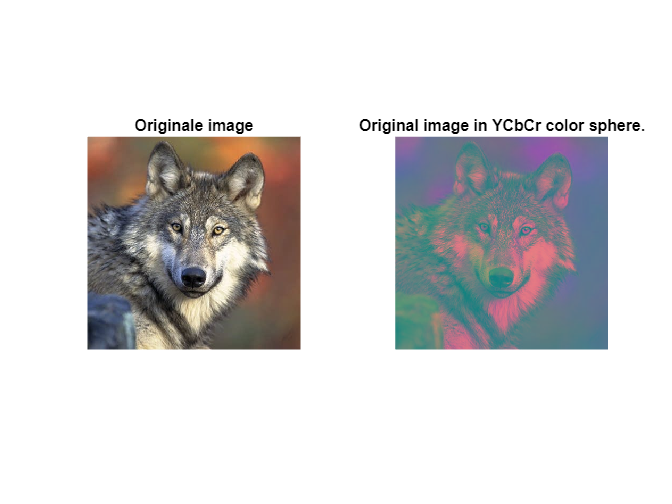

yMat = ones(400,400);
cbMat =  yMat;
crMmat = yMat;

ycb = rgb2ycbcr(img);
figure;
    layout1 = tiledlayout(1,2);
    nexttile
    imshow(img, [])
    title("Originale image")
    nexttile
    imshow(ycb, [])
    title("Original image in YCbCr color sphere.")

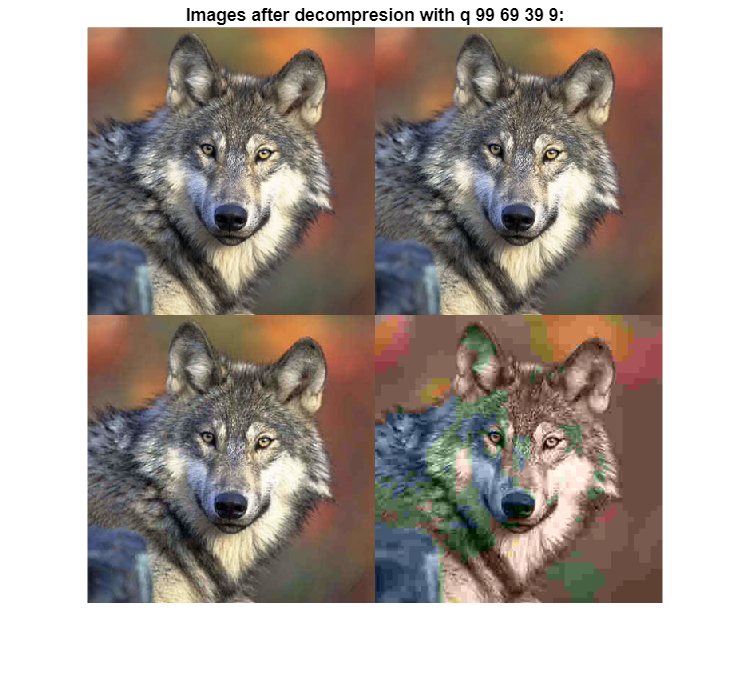

% Quality var = q
[imgOut11, comp11] = compresing(99, QC, QL, img);
[imgOut21, comp21] = compresing(69, QC, QL, img);
[imgOut31, comp31] = compresing(39, QC, QL, img);
[imgOut41, comp41] = compresing(9, QC, QL, img);

figure
    montage({imgOut11,imgOut21,imgOut31,imgOut41 })
    title("Images after decompresion with q 99 69 39 9:")


Q = [99;69;39;9];
Compresio_rate = [comp11+"%";comp21+"%";comp31+"%";comp41+"%"];
table(Q,Compresio_rate)

ans = 4×2 table
    Q     Compresio_rate
    __    ______________

    99      "14.2821%"  
    69      "6.6194%"   
    39      "5.2881%"   
     9      "2.3529%"   


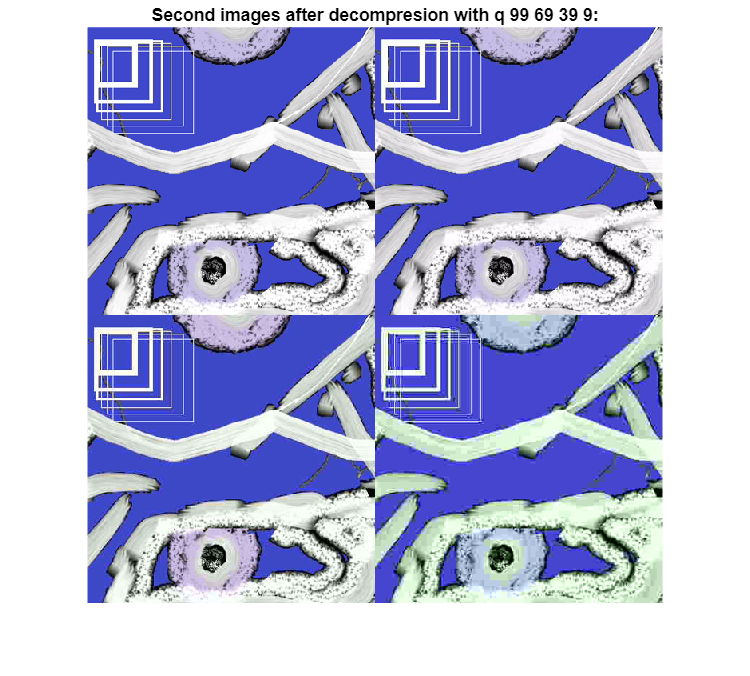

[imgOut12, comp12] = compresing(99, QC, QL, img2);
[imgOut22, comp22] = compresing(69, QC, QL, img2);
[imgOut32, comp32] = compresing(39, QC, QL, img2);
[imgOut42, comp42] = compresing(9, QC, QL, img2);

figure
    montage({imgOut12,imgOut22,imgOut32,imgOut42 })
    title("Second images after decompresion with q 99 69 39 9:")


Q_2 = [99;69;39;9];
Compresio_rate_2 = [comp12+"%";comp22+"%";comp32+"%";comp42+"%"];
table(Q_2,Compresio_rate_2)

ans = 4×2 table
    Q_2    Compresio_rate_2
    ___    ________________

    99        "22.436%"    
    69        "8.2844%"    
    39        "6.0177%"    
     9        "3.1142%"    


• Kvalitatívne **vyhodnoťte** vplyv atribútu “kvalita” na výslednú stratu kvality obrázka. 

    Pri akej hodnote atribútu došlo k rozpoznateľnej strate kvality ?

K rozpoznatelnej zmene kvality došlo pri q < 10, pri prvom obrazku pri druhom naznaky bolo možne pozorovať i okolo q ~ 30.

• Kvantitatívne **vyhodnoťte** kompresný pomer (v %) pre rôzne hodnoty atribútu “kvalita”. 

Vysledky z tejto časti vyšli anti-intuitivne. Pričom čim Q bolo väčšie, tým bol väčší kompresný pomer, a tým bola kvalita obrazku vyzšia.

**Úloha 2: JPEG 2000 kompresia**

Naprogramujte základný algoritmus pre JPEG 2000 – zjednodušený algoritmus pre kompresiu a dekompresiu. 

Algoritmus naprogramujte dvoma spôsobmi:

- S jednou úrovňou (single level wavelet compression)

- Dyadická dekompozícia (viacúrovňová)

## Single level wavelet compression

- Definujte „extension mode“

- Definujte „wavelet type“

- Načitajte obrázok

- Spočítajte 2 dimenzionálnu DWT ( funkcia dwt2() )

- Vizualizujte DWT koeficienty

- Použite vhodný multiplikatívny faktor (napr. 10) pre lepšiu vizualizáciu

- Skalárne kvantizujte s vami definovaným kvantizačným krokom Delta $q=\textrm{sign}\left(y\right)\left\lfloor \frac{\left|y\right|}{\Delta_b }\right\rfloor$

- Všetky kroky spravte v inverznom poradí (dekompresia)

## Dyadic decomposition

- Pre výpočet dyadickej dekompozície použite funkciu wavedec2()

- Vizualizujte výstupné obrázky pomocou funkcie wrcoef2()

- Vizualizujte pre ľubovoľnú úroveň dekompozície všetky štyri matice v rámci 1 sub-plotu (aproximačná, horizontálna, vertikálna, diagonálna)

- Skalárna kvantizácia koeficientov$\;q=\textrm{sign}\left(y\right)\left\lfloor \frac{\left|y\right|}{\Delta_b }\right\rfloor$

- Všetky kroky spravte v inverznom poradí (dekompresia)

**Vykonajte kvalitatívne porovnanie** komprimovaného obrázka pre rôzne (Vaše závery vhodne ilustrujte priblíženými vizualizaciami, kde je viditeľný vplyv zmeny týchto parametrov. Pre každý nasledujúci parameter napr. v rámci sub-plotu):

- hodnoty parametru delta (stačia 3)

- počet úrovní dekompozície (stačia 3)

- wavelet funkcie (stačia 2)

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

### Single level wavelet compression

#### Definujte „extension mode“

extensionMode = "zpd"

extensionMode = "zpd"

#### Definujte „wavelet type“

waveletType = "haar"

waveletType = "haar"

#### Načitajte obrázok

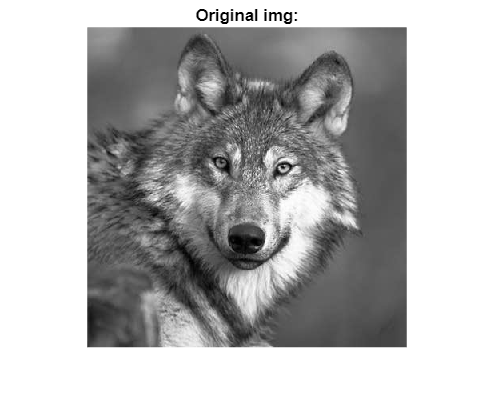

secondImg = rgb2gray(imread('wolf2.png'));
figure;
    imshow(secondImg,[])
    title("Original img:")

size(secondImg)

ans =    400   400


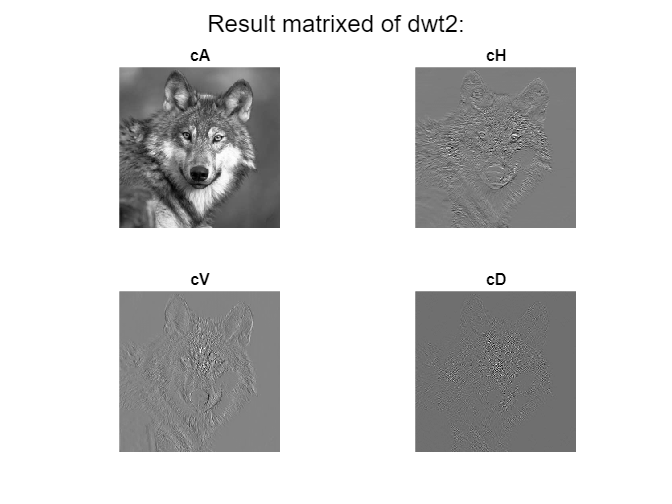

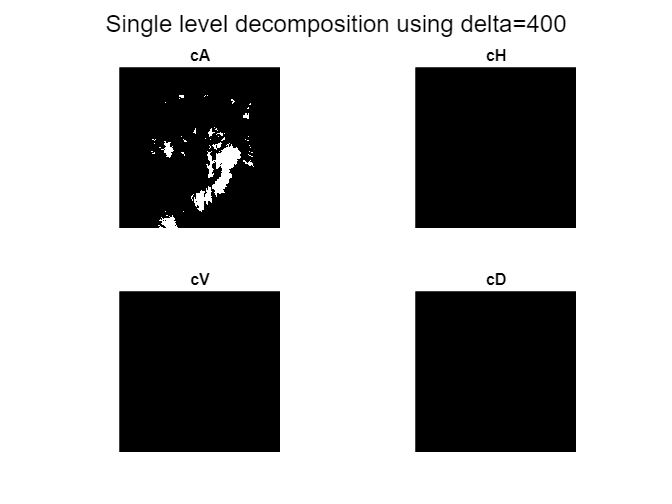

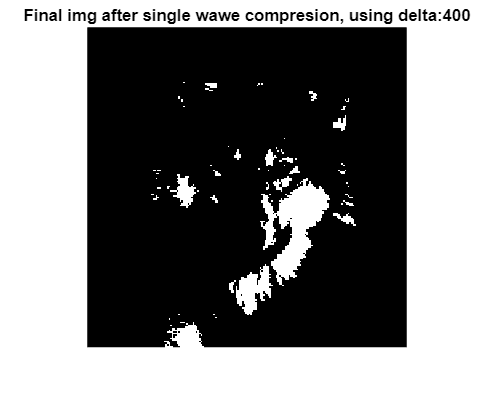

% Single level wavelet compression
imgAfter_S400_H = singleWaveComp(secondImg, extensionMode, "haar", 400, 1, 1, 1);

imgAfter_S200_H = singleWaveComp(secondImg, extensionMode, "haar", 200, 0, 0, 0);
imgAfter_S100_H = singleWaveComp(secondImg, extensionMode, "haar", 100, 0, 0, 0);
imgAfter_S50_H = singleWaveComp(secondImg, extensionMode, "haar", 50, 0, 0, 0);

imgAfter_S100_D = singleWaveComp(secondImg, extensionMode, "db2", 100, 0, 0, 0);
imgAfter_S50_D = singleWaveComp(secondImg, extensionMode, "db2", 50, 0, 0, 0);

### Dyadic decomposition

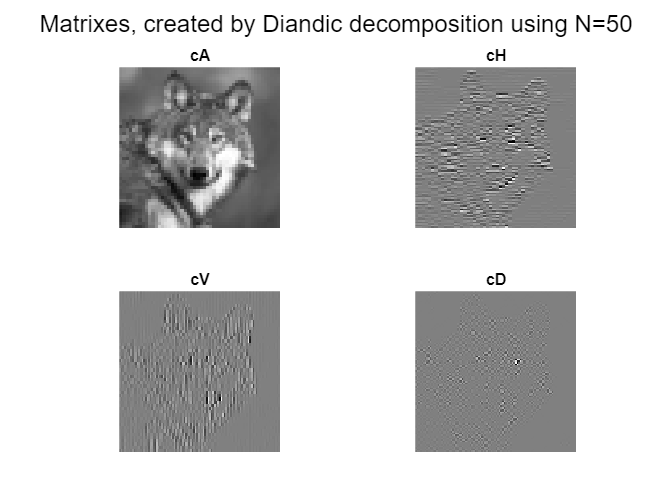

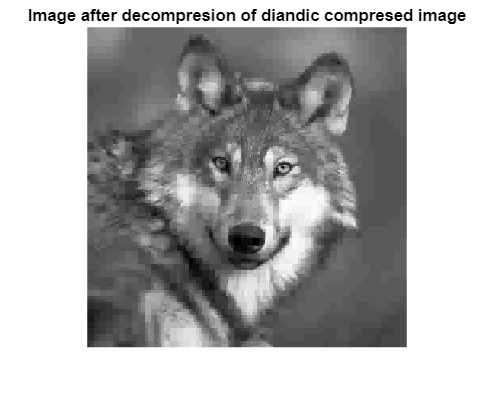

% Dyadic decomposition
imgAfter_D3_H = dianComp(secondImg, "haar", 50, 1, 1);

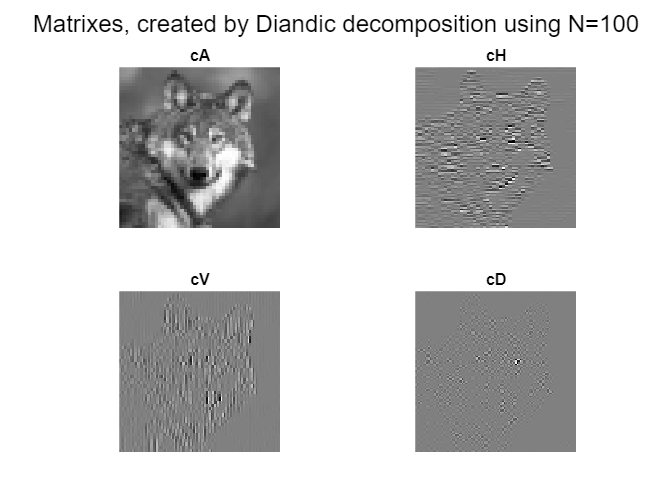

imgAfter_D6_H = dianComp(secondImg, "haar", 100, 1, 0);

imgAfter_D12_H = dianComp(secondImg, "haar", 200, 0, 0);
imgAfter_D24_H = dianComp(secondImg, "haar", 400, 0, 0);

imgAfter_D3_D = dianComp(secondImg, "db2", 50, 0, 0);
imgAfter_D6_D = dianComp(secondImg, "db2", 100, 0, 0);

**Vykonajte kvalitatívne porovnanie** komprimovaného obrázka pre rôzne (Vaše závery vhodne ilustrujte priblíženými vizualizaciami, kde je viditeľný vplyv zmeny týchto parametrov. Pre každý nasledujúci parameter napr. v rámci sub-plotu):

- hodnoty parametru delta (stačia 3)

delta:

Pre delta parameter bol vybrané 4 hodnoty od 50 ktore boli 2 predosleho, v takomto zostavení sme spozorovali znatelné znehodnotenia obrazka pri delta=100, kedy pri delta=400 obrazok bol minimalne rozpoznatelny, zo sýtymy farbamy.

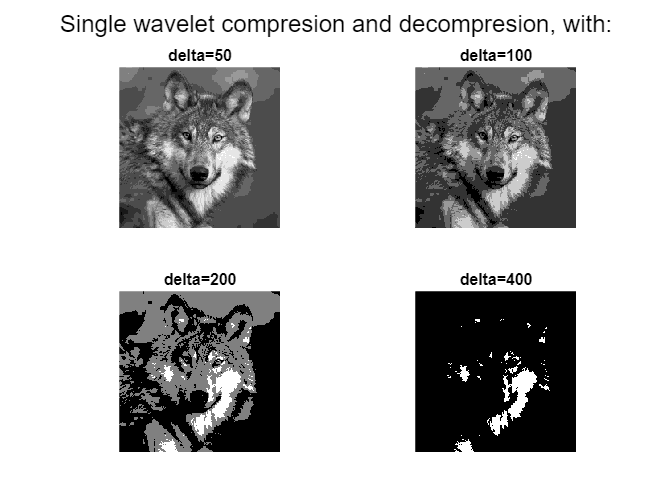

       figure;
            subplot(2,2,1);
            imshow(imgAfter_S50_H, [])
            title("delta=50")
        
            subplot(2,2,2);
            imshow(imgAfter_S100_H, [])
            title("delta=100")
        
            subplot(2,2,3);
            imshow(imgAfter_S200_H, [])
            title("delta=200")
        
            subplot(2,2,4);
            imshow(imgAfter_S400_H, [])
            title("delta=400")
            sgtitle("Single wavelet compresion and decompresion, with:")

- počet úrovní dekompozície (stačia 3)

N: podobne ako pri single wave compresií, pri dyadic sme pozorovali prvé znatené znehodnotene pri N=100, kedy pri N=400 obrazok bol značne znehodnotený i keď stále obsahoval viacej informácií ako pri delte=400. Avšak single wave mal tendenciu zachovavania väčších detailov plošne, ako je vidieť pri páre obrazkov delta=200 a N=200.

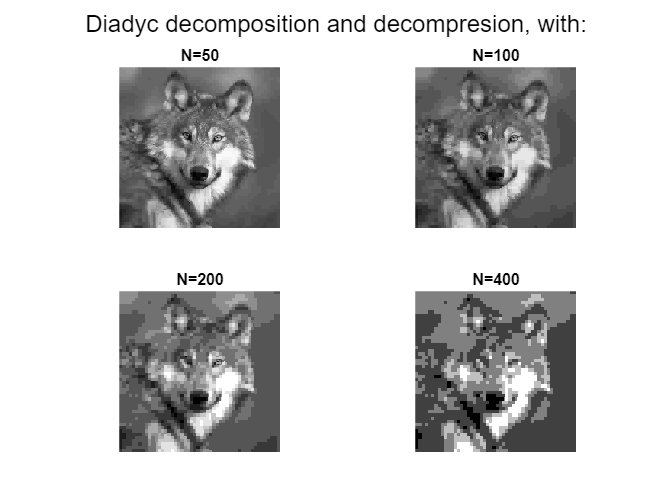

         figure;
            subplot(2,2,1);
            imshow(imgAfter_D3_H, [])
            title("N=3")
        
            subplot(2,2,2);
            imshow(imgAfter_D6_H, [])
            title("N=100")
        
            subplot(2,2,3);
            imshow(imgAfter_D12_H, [])
            title("N=200")
        
            subplot(2,2,4);
            imshow(imgAfter_D24_H, [])
            title("N=400")
            sgtitle("Diadyc decomposition and decompresion, with:")

- wavelet funkcie (stačia 2)

wname: V rámci rôznych wavelet typov sme porovnávali typy "haar" a "db2", kvôli najdenému znatelnému rozdielu v dyadic decomposet obrazokv (pravé obrazky), kde by wavelet type "type" bol obrazok detailnejší ako pre "haar".

-     "haar       delta=100, N=6

-     "db2"       delta=100, N=6

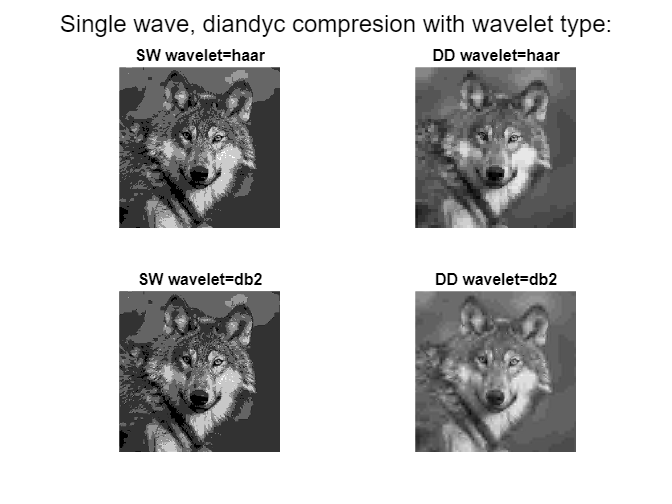

         figure;
            subplot(2,2,1);
            imshow(imgAfter_S100_H, [])
            title("SW wavelet=haar")
        
            subplot(2,2,2);
            imshow(imgAfter_D6_H, [])
            title("DD wavelet=haar")
        
            subplot(2,2,3);
            imshow(imgAfter_S100_D, [])
            title("SW wavelet=db2")
        
            subplot(2,2,4);
            imshow(imgAfter_D6_D, [])
            title("DD wavelet=db2")
            sgtitle("Single wave, diandyc compresion with wavelet type:")

Funkcie

function [imgAfter] = singleWaveComp(grayImg, extensionMode, waveName, delta, flag1, flag2, flag3)

####         Spočítalisme 2-dimenzionálnu DWT ( pomocout funkcia dwt2() )

    [matImg1 matImg2 matImg3 matImg4] = dwt2(grayImg, waveName, "mode", extensionMode);

####         Vizualizujte DWT koeficienty

    if flag1
        figure;
            subplot(2,2,1);
            imshow(matImg1, [])
            title("cA")
        
            subplot(2,2,2);
            imshow(matImg2, [])
            title("cH")
        
            subplot(2,2,3);
            imshow(matImg3, [])
            title("cV")
        
            subplot(2,2,4);
            imshow(matImg4, [])
            title("cD")
            sgtitle('Result matrixed of dwt2:')
    end

####          Skalárne kvantizujte s vami definovaným kvantizačným krokom Delta $q=\textrm{sign}\left(y\right)\left\lfloor \frac{\left|y\right|}{\Delta_b }\right\rfloor$

    kvantMat1 = sign(matImg1).*floor((abs(matImg1)/delta));
    kvantMat2 = sign(matImg2).*floor((abs(matImg2)/delta));
    kvantMat3 = sign(matImg3).*floor((abs(matImg3)/delta));
    kvantMat4 = sign(matImg4).*floor((abs(matImg4)/delta));
    if flag2
        figure;
            subplot(2,2,1);
            imshow(kvantMat1, [])
            title("cA")
        
            subplot(2,2,2);
            imshow(kvantMat2, [])
            title("cH")
        
            subplot(2,2,3);
            imshow(kvantMat3, [])
            title("cV")
        
            subplot(2,2,4);
            imshow(kvantMat4, [])
            title("cD")
            sgtitle("Single level decomposition using delta="+delta)
    end

####          Dekompresia

    imgAfter = uint8(idwt2(kvantMat1.*delta,kvantMat2.*delta,kvantMat3.*delta,kvantMat4.*delta, waveName));
    if flag3
        figure;
            imshow(imgAfter,[])
            title("Final img after single wawe compresion, using delta:"+delta)
    end
end

### Diandic dekompozicia

####     Vizualizovali sme pre delta úroveň dekompozície, všetky štyri matice v rámci 1 sub-plotu (aproximačná,         horizontálna, vertikálna, diagonálna), výstupné obrázky pomocou funkcie wrcoef2()

function [imgAfter] = dianComp(grayImg, waveName, delta, flag1, flag2)
    % Pre výpočet dyadickej dekompozície použite funkciu wavedec2()
    [C,S] = wavedec2(grayImg,3,waveName); 
    if flag1
        figure;
            subplot(2,2,1);
            imshow(wrcoef2("a",C,S,waveName), [])
            title("cA")
        
            subplot(2,2,2);
            imshow(wrcoef2("h",C,S,waveName), [])
            title("cH")
        
            subplot(2,2,3);
            imshow(wrcoef2("v",C,S,waveName), [])
            title("cV")
        
            subplot(2,2,4);
            imshow(wrcoef2("d",C,S,waveName), [])
            title("cD")
            sgtitle("Matrixes, created by Diandic decomposition using N="+delta)
    end

####             Skalárna kvantizácia koeficientov$\;q=\textrm{sign}\left(y\right)\left\lfloor \frac{\left|y\right|}{\Delta_b }\right\rfloor$

     c = sign(C).*floor(abs(C)/delta);

####              Dekompresia

     imgAfter  = waverec2(c,S,waveName);

####             Visualization of decompresed image

     if flag2
         figure;
            imshow(imgAfter, [])
            title("Image after decompresion of diandic compresed image")
     end
end

### Funckia pre 1. ulohu kompresie Jpg obrazka

function [imgAfter_rgb, compresion_degree] = compresing(q, QC, QL, img)
    all_zero = 0;
    yy = ones(400,400);
    cb = ones(400,400);
    cr = ones(400,400);
    alfa = 0;
    if q >= 1 && q < 50
        alfa = 50 / q;
    elseif q >= 50 && q <= 100
        alfa  = 2 - (q / 50);
    end
    imgAfter = ones(400,400,3);
    for ii = 1:50
        for jj = 1:50
           % Calc. insertion indexes
           i_indxTo = ii*8;
           j_indxTo = jj*8;

           i_indxFrom = i_indxTo - 7;
           j_indxFrom = j_indxTo - 7;

           indxToY = [8*ii,8*jj];
           indxFromY = indxToY - [7,7];
            
           % Create ycbcr mat_400x400x3
           mat = img(i_indxFrom:i_indxTo, j_indxFrom:j_indxTo,:);
           changed_mat =  rgb2ycbcr(mat);
           mat_cb = changed_mat(:,:,2);
           mat_cr = changed_mat(:,:,3);
           
           % Separate into channels and downsample compress
           cb_tmp = downsample(downsample(mat_cb,2)', 2)';
           cr_tmp = downsample(downsample(mat_cr,2)', 2)';
           y = changed_mat(:,:,1);
    
    
           % Transform with DCT2 and alfa value
           alfaQc = (alfa * downsample(downsample(QC,2)', 2)');
           alfaQl = (alfa * QL);
    
           compCb = round(dct2(cb_tmp)./alfaQc);
           compCr = round(dct2(cr_tmp)./alfaQc);
           compY = round(dct2(y)./alfaQl);
           all_zero = all_zero + (64 - nnz(compCb)) + (64 - nnz(compCr)) + (64 - nnz(compY));
           % De-compresia
           [outCb, outCr, outY] = de_compresing(alfa, QC, QL, alfaQc, compY, compCb, compCr);
            
            % Insert choosen boxes into channle matrixes
            
           yy(i_indxFrom:i_indxTo, j_indxFrom:j_indxTo) = outY;
           cb(i_indxFrom:i_indxTo, j_indxFrom:j_indxTo) = outCb;
           cr(i_indxFrom:i_indxTo, j_indxFrom:j_indxTo) = outCr;
        end
    end
    % inverse ycbcr to rgb
    % yy cb cr
    imgAfter = uint8(cat(3, yy,cb,cr));
    
    imgAfter_rgb = ones(400,400,3);
    imgAfter_rgb = ycbcr2rgb(imgAfter);
    
   format("shortG")
   compresion_degree = (1 - (all_zero/(400*400*3))) * 100;
end

### Funkcia 1. ulohy pre dekompresiu

function [cb, cr, y] = de_compresing(alfa, QC, QL, alfaQc, yMat, cbMat, crMat)
       % Upsample and De-Compress with DCT2 and alfa value
       % alfaQc = (alfa * QC);
       alfaQl = (alfa * QL);

       % cbMat = kron(cbMat,zeros(2));
       % crMat = kron(crMat,zeros(2));

       compCb = ((idct2(cbMat.*alfaQc)));
       compCr = ((idct2(crMat.*alfaQc)));
       compY  = ((idct2(yMat.*alfaQl)));
        
       
       cb = imresize(compCb,2);
       cr = imresize(compCr,2);
       y = compY;
end